root = "C:\Users\anton\Documents\GitHub\foram-cnn\data\batch\";

tiffFiles = dir(strcat(root, "*.tif"));

numFiles = numel(tiffFiles);

data = zeros(925 ,932, numFiles, 'uint8');

for i = 1:numFiles
    data(:,:,i) = imread(strcat(root, tiffFiles(i).name));
end

threshold = graythresh(data);

data = imbinarize(data, threshold);

clear i; clear threshold;

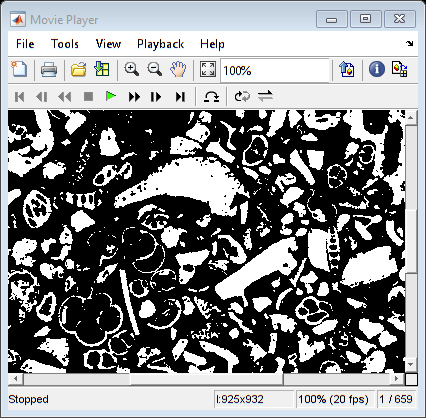

implay(data)

dark = data

save("myData", "dark")